Part 4 Fourier Analysis

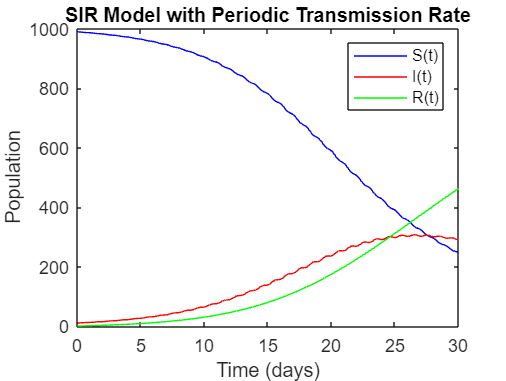

beta0 = 0.3; % Base transmission rate
A = 0.5; % Amplitude of variation
w = 2 * pi * 365 / 365; % Angular frequency
gamma = 0.1; % Recovery rate
N = 1000; % Total population
h = 0.1; % Time step size
T = 30; % Simulation duration in days

S0 = 990; I0 = 10; R0 = 0;
t = 0:h:T;

S = zeros(size(t)); 
I = zeros(size(t)); 
R = zeros(size(t));

% Initial values
S(1) = S0; I(1) = I0; R(1) = R0;

% Time-varying beta function
beta = @(t) beta0 * (1 + A * sin(w * t));

% Solve SIR model using Euler's method
for k = 1:length(t)-1
    dS = -beta(t(k)) * S(k) * I(k) / N;
    dI = beta(t(k)) * S(k) * I(k) / N - gamma * I(k);
    dR = gamma * I(k);
    
    S(k+1) = S(k) + h * dS;
    I(k+1) = I(k) + h * dI;
    R(k+1) = R(k) + h * dR;
end

figure;
plot(t, S, 'b', t, I, 'r', t, R, 'g');
legend('S(t)', 'I(t)', 'R(t)');
xlabel('Time (days)');
ylabel('Population');
title('SIR Model with Periodic Transmission Rate');

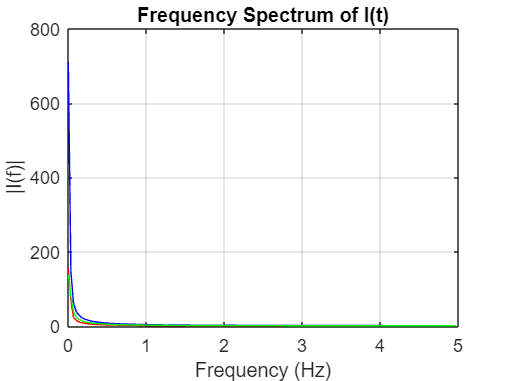


% Fourier 
Fs = 1 / h; 
NFFT = length(t)-1;
f = (0:NFFT/2-1) * Fs / NFFT;

% Compute FFT
I_fft = fft(I);
I_spectrum = abs(I_fft / NFFT);
I_spectrum = I_spectrum(1:NFFT/2);
S_fft = fft(S);
S_spectrum = abs(S_fft / NFFT);
S_spectrum = S_spectrum(1:NFFT/2);
R_fft = fft(R);
R_spectrum = abs(R_fft / NFFT);
R_spectrum = R_spectrum(1:NFFT/2);

% Plot spectrum
figure;
plot(f, I_spectrum, 'r',f, S_spectrum, 'b', f, R_spectrum, 'g' );
xlabel('Frequency (Hz)');
ylabel('|I(f)|');
title('Frequency Spectrum of I(t)');
grid on;

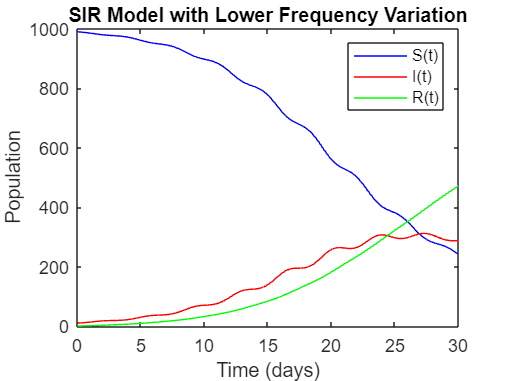


% lower angular frequency
w_low = 2 * pi * 100 / 365;
beta_low = @(t) beta0 * (1 + A * sin(w_low * t));

S_low = zeros(size(t)); 
I_low = zeros(size(t)); 
R_low = zeros(size(t));

S_low(1) = S0; I_low(1) = I0; R_low(1) = R0;

for k = 1:length(t)-1
    dS = -beta_low(t(k)) * S_low(k) * I_low(k) / N;
    dI = beta_low(t(k)) * S_low(k) * I_low(k) / N - gamma * I_low(k);
    dR = gamma * I_low(k);
    
    S_low(k+1) = S_low(k) + h * dS;
    I_low(k+1) = I_low(k) + h * dI;
    R_low(k+1) = R_low(k) + h * dR;
end
figure;
plot(t, S_low, 'b', t, I_low, 'r', t, R_low, 'g');
legend('S(t)', 'I(t)', 'R(t)');
xlabel('Time (days)');
ylabel('Population');
title('SIR Model with Lower Frequency Variation');

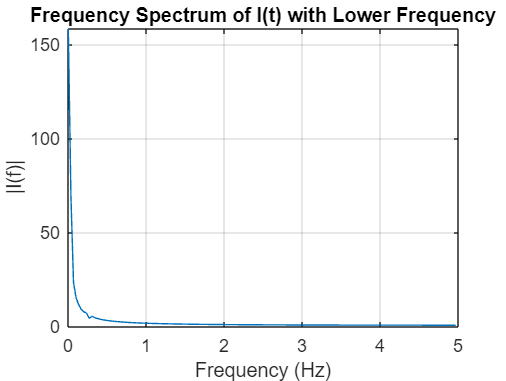


% Fourier Transform for lower frequency
I_low_fft = fft(I_low);
I_low_spectrum = abs(I_low_fft / NFFT);
I_low_spectrum = I_low_spectrum(1:(NFFT)/2);

figure;
plot(f, I_low_spectrum);
xlabel('Frequency (Hz)');
ylabel('|I(f)|');
title('Frequency Spectrum of I(t) with Lower Frequency');
grid on;